Function to return the exact path loss predicted by the 2 ray, ground reflection model returned in dB

function PL = get2rayExactPL(distance, frequency, tx_height, rx_height, polarization, epsilon_r)
    % Find the wavelength of the signal in meter
    lambda = physconst('LightSpeed')/frequency;
    
    % Find the total length of the (ground) reflected ray in meters
    ground_ray_length = (tx_height + rx_height).^2 + distance.^2;
    ground_ray_length = sqrt(ground_ray_length);
    
    % Find line of sight distance
    line_of_sight_length = (tx_height - rx_height).^2 + distance.^2;
    line_of_sight_length = sqrt(line_of_sight_length);
    
    % Find the incedent angle in radians
    theta = (tx_height+rx_height)./ground_ray_length;
    theta = asin(theta);
    
    % Find permitivity 
    epsilon = 8.854e-12*epsilon_r;
    
    % Find z based on polarization 
    switch polarization
        case 'horizontal'
            z = sqrt(epsilon - (cos(theta)).^2);    
        case 'vertical'
            z = sqrt(epsilon - (cos(theta)).^2)./epsilon;                    
        otherwise
            disp("You didn't enter the polarization correctly")
            PL = 100000;
            return
    end
    
    % Find the reflection coeff
    gamma = sin(theta) - z;
    gamma = gamma./(sin(theta) + z);
    
    % Find the line of sight path loss
    path_loss_line_of_sight = 4*pi.*line_of_sight_length;
    path_loss_line_of_sight = lambda./path_loss_line_of_sight;
    path_loss_line_of_sight = exp(-j*2*pi*line_of_sight_length./lambda).*path_loss_line_of_sight;
    path_loss_line_of_sight = real(path_loss_line_of_sight);
    
    % Find the ground reflected ray path loss
    path_loss_reflected_ray = 4*pi.*ground_ray_length;
    path_loss_reflected_ray = lambda.*gamma./path_loss_reflected_ray;
    path_loss_reflected_ray = exp(-j*2*pi*ground_ray_length./lambda).*path_loss_reflected_ray;
    path_loss_reflected_ray = real(path_loss_reflected_ray);
    
    % Find the exact 2 ray path loss
    path_loss_2ray = path_loss_reflected_ray + path_loss_line_of_sight;
    path_loss_2ray = path_loss_2ray.^2;
    path_loss_2ray = 1./path_loss_2ray;
    
    PL = 10*log10(path_loss_2ray);
end


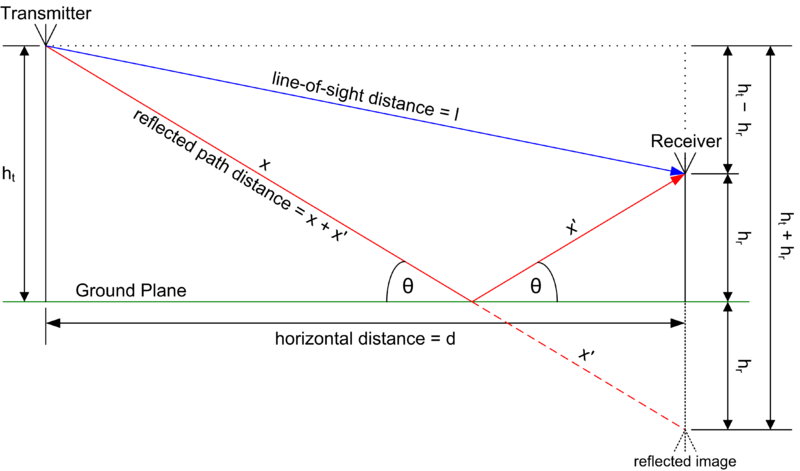

s(t) : transmitted signal

l: length (line of sight)

x+x': length of ground reflected ray

Ggr, Glos: antenna gain

E{}: Expected value/ average